2 Point-wise thresholding of gradient magnitudes

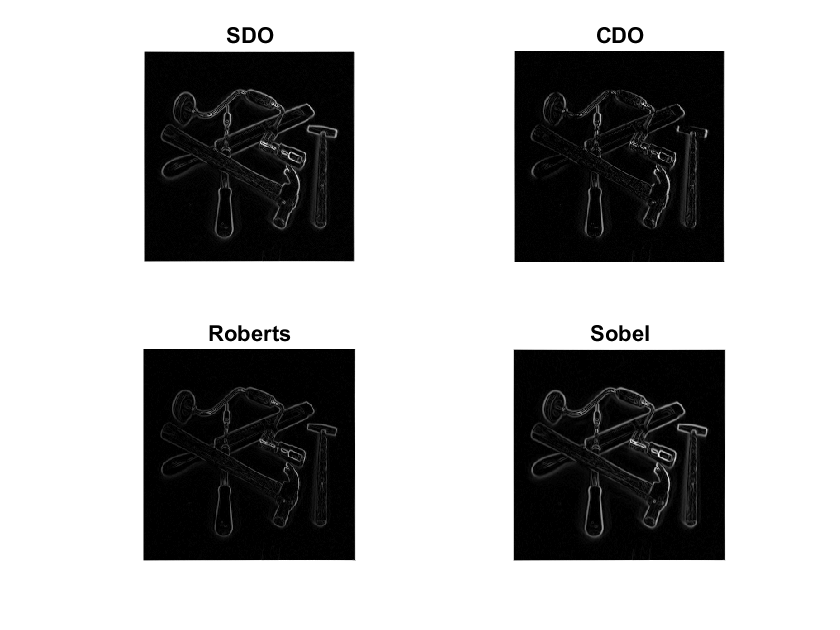

clear;

tools = few256;

[dxtools_1, dytools_1] = deriv(tools, 1, 'same');
[dxtools_2, dytools_2] = deriv(tools, 2, 'same');
[dxtools_3, dytools_3] = deriv(tools, 3, 'same');
[dxtools_4, dytools_4] = deriv(tools, 4, 'same');

gradmagntools_1 = sqrt(dxtools_1.^2 + dytools_1.^2);
gradmagntools_2 = sqrt(dxtools_2.^2 + dytools_2.^2);
gradmagntools_3 = sqrt(dxtools_3.^2 + dytools_3.^2);
gradmagntools_4 = sqrt(dxtools_4.^2 + dytools_4.^2);

figure;

subplot(2,2,1);
showgray(gradmagntools_1);
title('SDO');

subplot(2,2,2);
showgray(gradmagntools_2);
title('CDO');

subplot(2,2,3);
showgray(gradmagntools_3);
title('Roberts');

subplot(2,2,4);
showgray(gradmagntools_4);
title('Sobel');

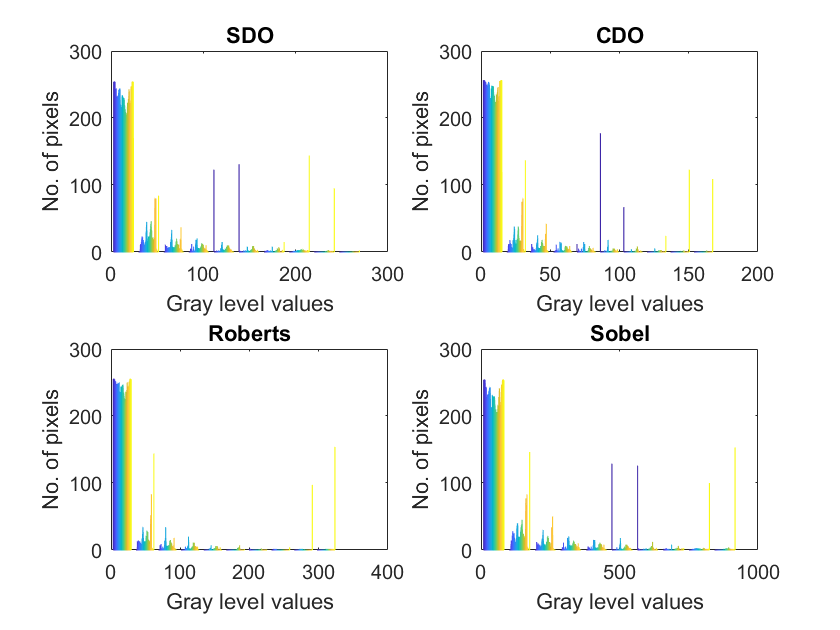


figure;

subplot(2,2,1);
hist(gradmagntools_1);
xlabel('Gray level values')
ylabel('No. of pixels');
title('SDO');

subplot(2,2,2);
hist(gradmagntools_2);
xlabel('Gray level values')
ylabel('No. of pixels');
title('CDO');

subplot(2,2,3);
hist(gradmagntools_3);
xlabel('Gray level values')
ylabel('No. of pixels');
title('Roberts');

subplot(2,2,4);
hist(gradmagntools_4);
xlabel('Gray level values')
ylabel('No. of pixels');
title('Sobel');

Threshold on first component

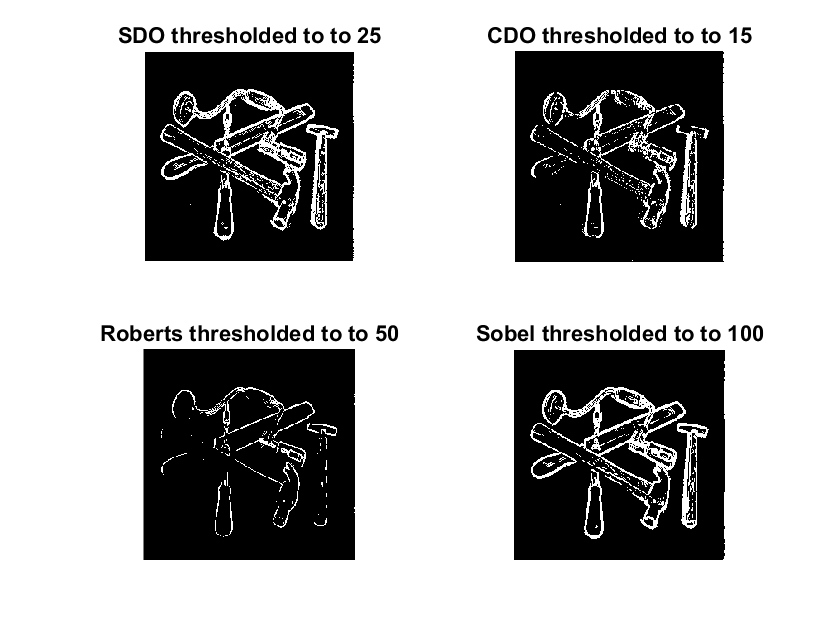

threshold_1 = 25;threshold_2 = 15;threshold_3 = 50;threshold_4 = 100;

figure;

subplot(2,2,1);
showgrey((gradmagntools_1 - threshold_1) > 0)
title(sprintf('SDO thresholded to to %d', threshold_1));

subplot(2,2,2);
showgrey((gradmagntools_2 - threshold_2) > 0)
title(sprintf('CDO thresholded to to %d', threshold_2));

subplot(2,2,3);
showgrey((gradmagntools_3 - threshold_3) > 0)
title(sprintf('Roberts thresholded to to %d', threshold_3));

subplot(2,2,4);
showgrey((gradmagntools_4 - threshold_4) > 0)
title(sprintf('Sobel thresholded to to %d', threshold_4));

Threshold on the second component

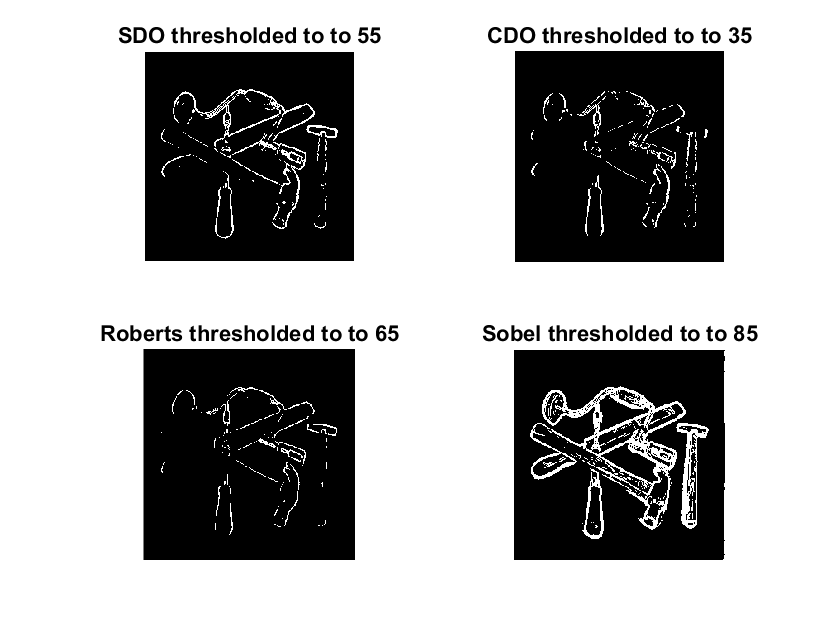

threshold_1 = 55;threshold_2 = 35;threshold_3 = 65;threshold_4 = 85;

figure;
title('Threshold on the second component')

subplot(2,2,1);
showgrey((gradmagntools_1 - threshold_1) > 0)
title(sprintf('SDO thresholded to to %d', threshold_1));

subplot(2,2,2);
showgrey((gradmagntools_2 - threshold_2) > 0)
title(sprintf('CDO thresholded to to %d', threshold_2));

subplot(2,2,3);
showgrey((gradmagntools_3 - threshold_3) > 0)
title(sprintf('Roberts thresholded to to %d', threshold_3));

subplot(2,2,4);
showgrey((gradmagntools_4 - threshold_4) > 0)
title(sprintf('Sobel thresholded to to %d', threshold_4));